# Entrega Laboratorio DAQ con IMU de dispositivos móviles para reconstrucción y clasificación movimiento

https://github.com/Lapd1103/Pr-ctica-Karts

Laura Alejadra Paez Daza - lpaezd@unal.edu.co

Juan Camilo Aguilar Coronado - jaguilarc@unal.edu.co

Para realizar esta practica se tomaron datos del movimiento de un kart con la IMU de un celular y la herramienta Edge Impulse. 

La idea es poder reconstruir la trayectoria aproximada de la curva. 

### Importación de Datos

Inicialmente se realiza la extracción de los datos del archivo JSON entregado por Edge Impulse. El archivo utilizado fue modificado para permitir esta lectura. 

fileName = 'DatosPistaEgui.json'; % filename in JSON extension
fid = fopen(fileName) % Opening the file

fid = 3

raw = fread(fid,inf); % Reading the contents
str = char(raw'); % Transformation
fclose(fid); % Closing the file


data = jsondecode(str); % Using the jsondecode function to parse JSON from string
sensors=table2array(struct2table(data.sensors));

DatosPista1 = array2table(data.values);
DatosPista1 = renamevars(DatosPista1,DatosPista1.Properties.VariableNames, sensors(:, 1)');

DatosPista1 = DatosPista1(:, 1:6)

DatosPista1 = 5000×6 table
    accX    accY    accZ    gyroX    gyroY    gyroZ
    ____    ____    ____    _____    _____    _____

      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0         0       0 
      0        0       0       0        


%Extracción de valores de aceleración y velocidad en 3 ejes
aceleracion_X = table2array(DatosPista1(:, 1));
aceleracion_Y = table2array(DatosPista1(:, 2));
aceleracion_Z = table2array(DatosPista1(:, 3));
vel_angular_X = table2array(DatosPista1(:, 4))*pi/180;
vel_angular_Y = table2array(DatosPista1(:, 5))*pi/180;
vel_angular_Z = table2array(DatosPista1(:, 6))*pi/180;

%Para dejar las señales en terminos del tiempo, se hizo relacion entre
%frecuencia de muestreo(Fs) y tiempo
Fs = 62.5; %[Hz]
T = 1 / Fs; %[seg]
N = length(aceleracion_X); % N° muestras

t = 0:T:T*(N-1)

t =          0    0.0160    0.0320    0.0480    0.0640    0.0800    0.0960    0.1120    0.1280    0.1440    0.1600    0.1760    0.1920    0.2080    0.2240    0.2400    0.2560    0.2720    0.2880    0.3040    0.3200    0.3360    0.3520    0.3680    0.3840    0.4000    0.4160    0.4320    0.4480    0.4640    0.4800    0.4960    0.5120    0.5280    0.5440    0.5600    0.5760    0.5920    0.6080    0.6240    0.6400    0.6560    0.6720    0.6880    0.7040    0.7200    0.7360    0.7520    0.7680    0.7840


Para poder analizar los datos se ubica la frecuencia de muestreo con que se midieron los datos que en este caso fue de 62.5, a partir de este dato se obtiene el periodo de muestreo con el cual se realiará lel proceso de ubicar el cuerpo en el tiempo. De la medición se obtuvieron las aceleraciones lineales (incluyendo la gravedad) así como las velocidades angulares del cuerpo. 

En seguida se pueden ver las gráficas de los datos como fueron entregados por la IMU del celular. 

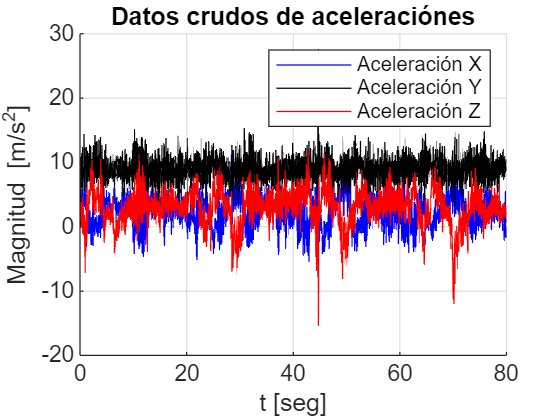

%Grafica de aceleraciónes
figure();
hold on;  
plot(t, aceleracion_X, 'b');
plot(t, aceleracion_Y, 'k');
plot(t, aceleracion_Z, 'r');

legend('Aceleración X','Aceleración Y','Aceleración Z');
xlabel('t [seg]');
ylabel('Magnitud [m/s^2]');
title('Datos crudos de aceleraciónes');
grid on;

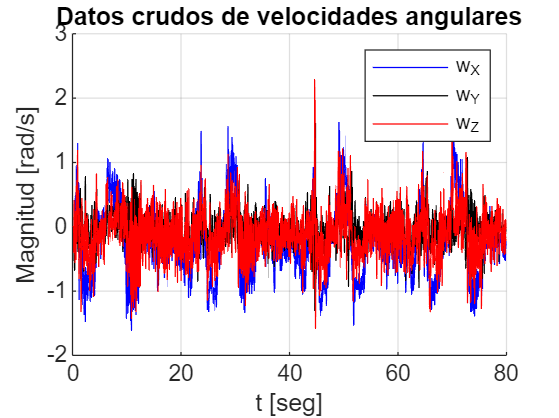



%hold on;  %Grafica de velocidades angulares
figure;
hold on;
plot(t, vel_angular_X, 'b');
plot(t, vel_angular_Y, 'k');
plot(t, vel_angular_Z, 'r');

legend('w_X','w_Y','w_Z');
xlabel('t [seg]');
ylabel('Magnitud [rad/s]');
title('Datos crudos de velocidades angulares');
grid on;


mag_aceleracion = sqrt(aceleracion_X.^2+aceleracion_Y.^2+aceleracion_Z.^2); 

Para poder utilizar estos datos es necesario realizar un filtrado de los datos para eliminar hasta donde sea posible el ruido causado por las vibraciones del motor en las mediciones, para esto es necesario considerar los espectros en frecuencia de las señales.

### Filtrado de las señales

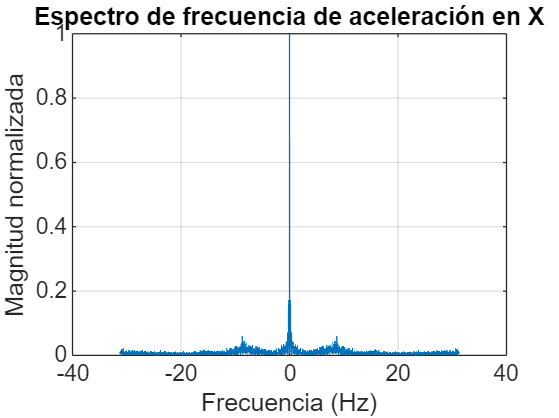

%Llama la función definida al final
espectro_frec(aceleracion_X,'aceleración en X',Fs)

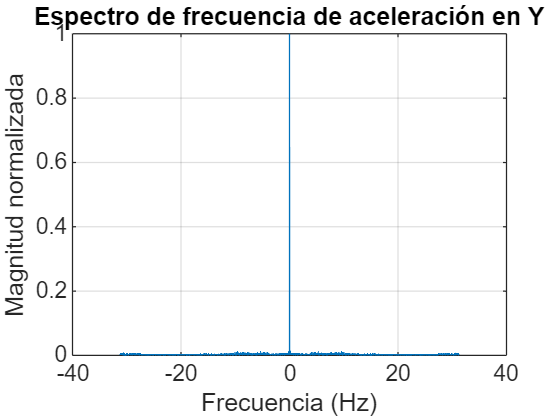

espectro_frec(aceleracion_Y,'aceleración en Y',Fs)

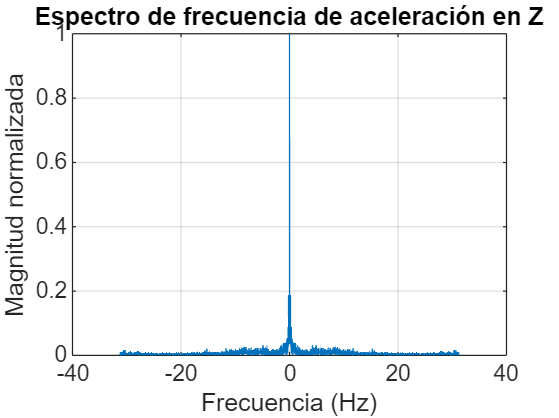

espectro_frec(aceleracion_Z,'aceleración en Z',Fs)

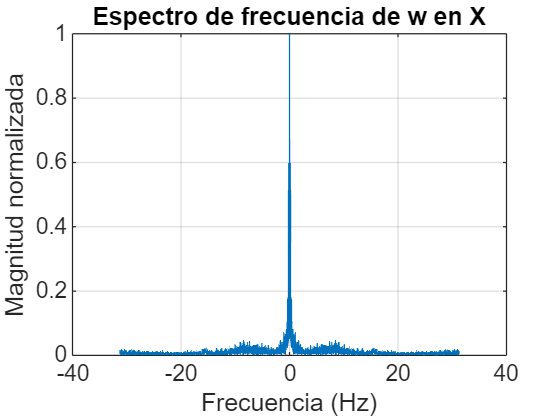

espectro_frec(vel_angular_X,'w en X',Fs)

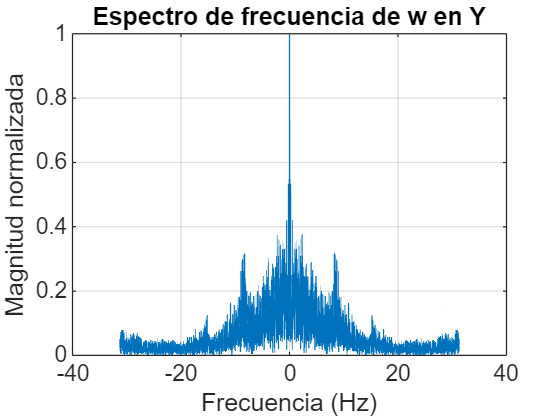

espectro_frec(vel_angular_Y,'w en Y',Fs)

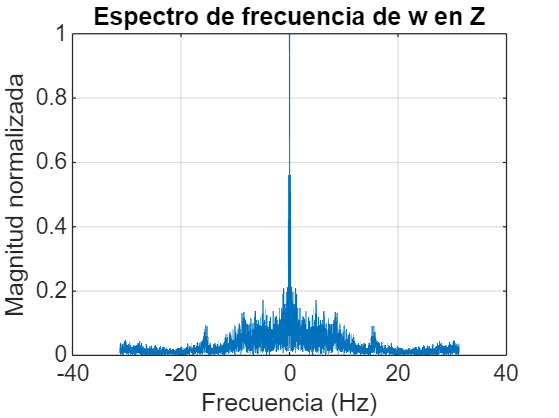

espectro_frec(vel_angular_Z,'w en Z',Fs)

En general de las gráficas se puede apreciar que las señales presentan un pico de ruido alrededor de los 8 Hz, sin embargo se eligió realizar el filtro con una frecuencia de corte de 5 Hz para tener un buen ancho de banda de los datos para la reconstrucción de la curva.

En la siguiente sección se puede observar la comparación entre las señales filtradas y las señales crudas junto con su respectivo espectro de frecuencia. 

#### Comparación de señales crudas vs filtradas

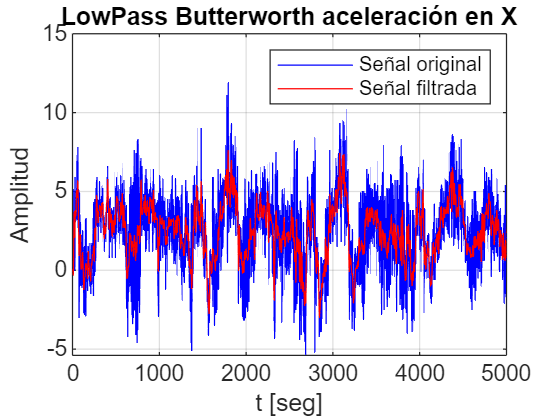

sf_aceleracionX = filtrar(Fs, 5, aceleracion_X, 'aceleración en X');

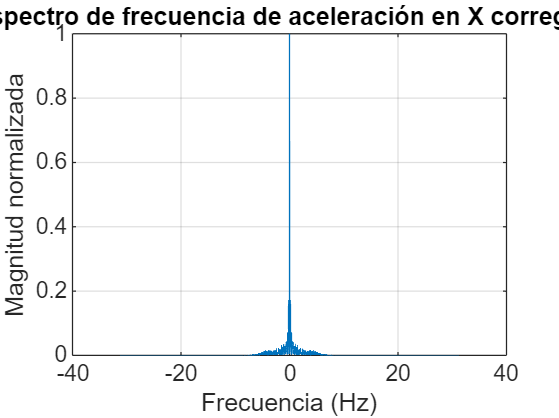

espectro_frec(sf_aceleracionX,'aceleración en X corregido',Fs)

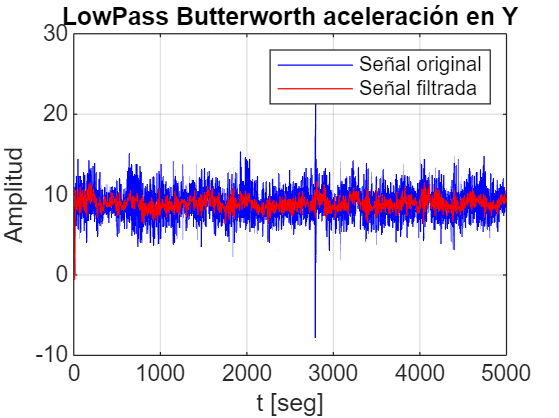



sf_aceleracionY = filtrar(Fs, 5, aceleracion_Y, 'aceleración en Y');

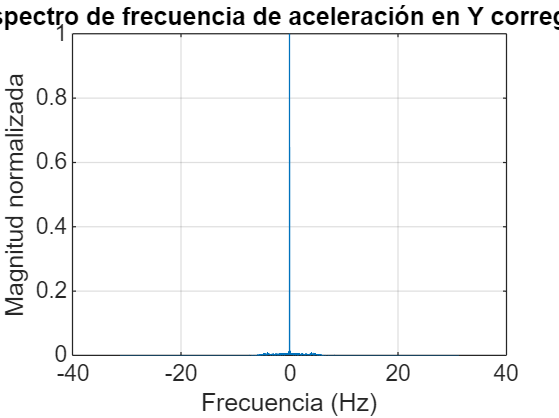

espectro_frec(sf_aceleracionY,'aceleración en Y corregido',Fs)

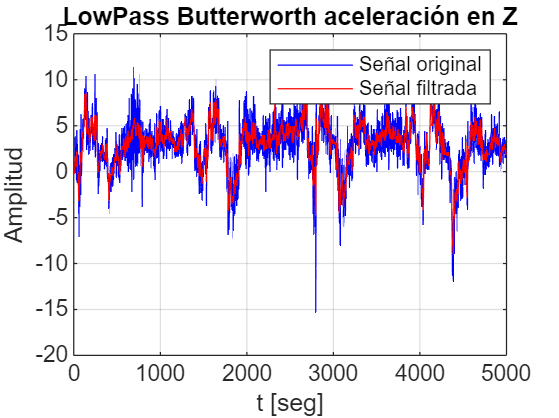


sf_aceleracionZ = filtrar(Fs, 5, aceleracion_Z, 'aceleración en Z');

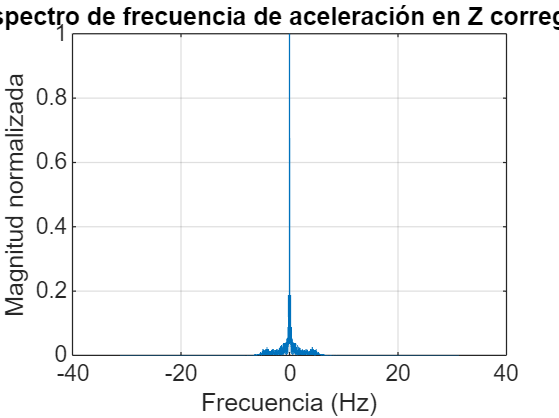

espectro_frec(sf_aceleracionZ,'aceleración en Z corregido',Fs)

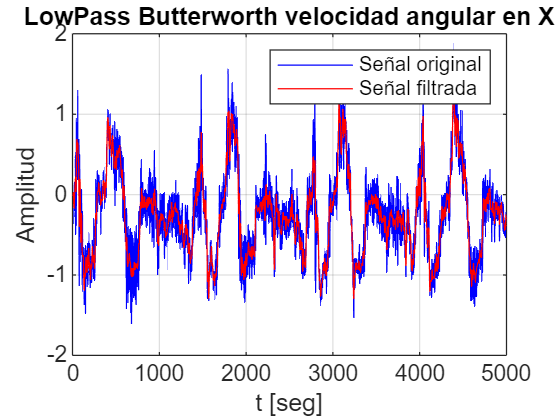


sf_vel_angularX = filtrar(Fs, 5, vel_angular_X, 'velocidad angular en X');

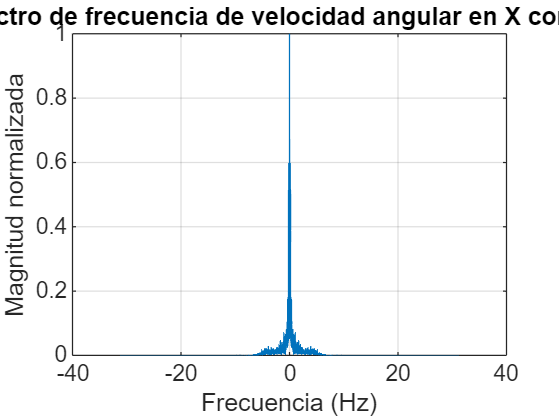

espectro_frec(sf_vel_angularX,'velocidad angular en X corregido',Fs)

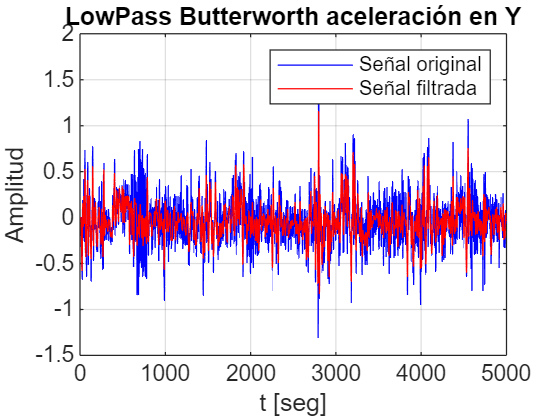



sf_vel_angularY = filtrar(Fs, 5, vel_angular_Y, 'aceleración en Y');

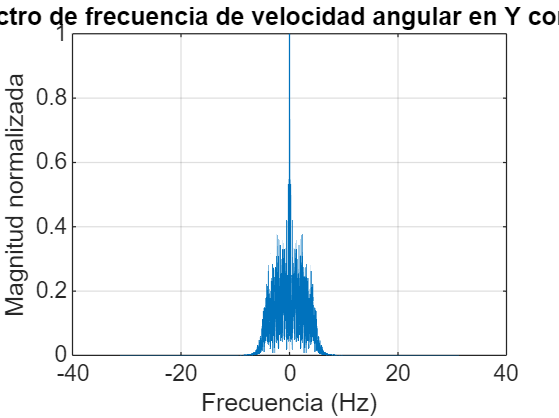

espectro_frec(sf_vel_angularY,'velocidad angular en Y corregido',Fs)

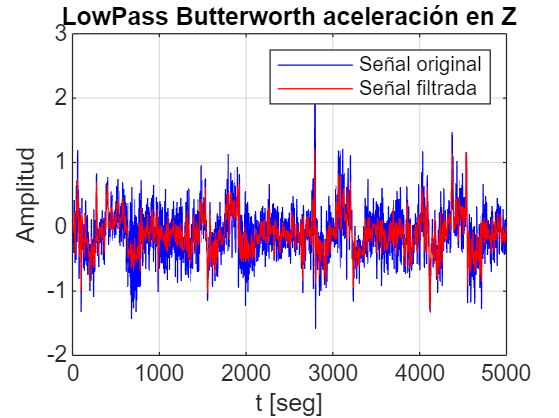


sf_vel_angularZ = filtrar(Fs, 5, vel_angular_Z, 'aceleración en Z');

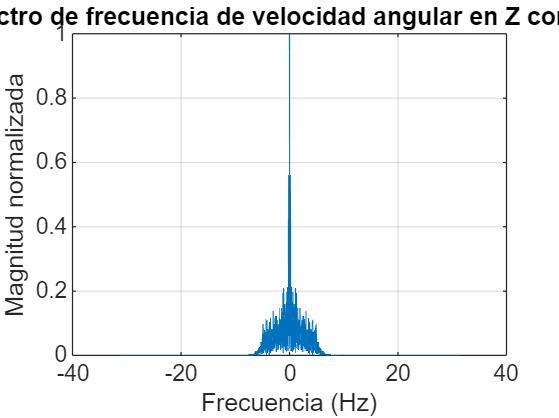

espectro_frec(sf_vel_angularZ,'velocidad angular en Z corregido',Fs)

### Reconstrucción de la señal

Para realizar la reconstrucción de la trayectoria inicialmente se tomó los valores de las velocidades angulares y con estos se determinó las posiciones angulares de cada vector. Para realizar esto se tomó el primer punto como la orientación absoluta, y luego cada orientación subsecuente se expresó en términos de este sistema absoluto con ayuda de la matríz de rotación que representa la orientación del sistema inmediatamente anterior. Seguido de esto, se "integró" la posición angular iterativamente a partir de las velocidades angulares, ahora en el marco de referencia absoluto. Esto es: 


$$\left\lbrack \begin{array}{c}
{\mathrm{vel}}_{\theta } \\
{\mathrm{vel}}_{\phi } \\
{\mathrm{vel}}_{\varphi } 
\end{array}\right\rbrack \left(t-1\right)=R\left(t-1\right)\times \left\lbrack \begin{array}{c}
\hat{{\mathrm{vel}}_{\theta } } \\
\hat{{\mathrm{vel}}_{\phi } } \\
\hat{{\mathrm{vel}}_{\varphi } } 
\end{array}\right\rbrack \left(t-1\right)$$



$$\left\lbrack \begin{array}{c}
\theta \\
\phi \\
\varphi 
\end{array}\right\rbrack \left(t\right)=\left\lbrack \begin{array}{c}
\theta \\
\phi \\
\varphi 
\end{array}\right\rbrack \left(t-1\right)+\left\lbrack \begin{array}{c}
{\mathrm{vel}}_{\theta } \\
{\mathrm{vel}}_{\phi } \\
{\mathrm{vel}}_{\varphi } 
\end{array}\right\rbrack \left(t-1\right)\times T\;$$


siendo T el periodo de muestreo.

Después con los ángulos encontrados se halla la nueva matriz de rotación que dará la orientación del siguiente sistema. 

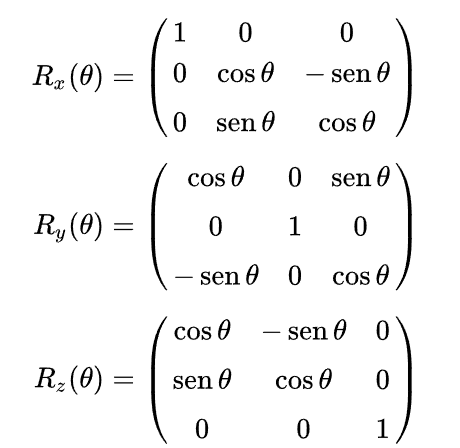

Con estas nuevas matrices de rotación para cada eje, al multiplicarlas entre si se obtiene la matriz de rotación total entre la orientación del sistema absoluto y el sistema relativo actual. Esta matríz debe ser utilizada para rotar los vectores de aceleración lineal del mismo modo que anteriormente:


$$\left\lbrack \begin{array}{c}
{\mathrm{acc}}_x \\
{\mathrm{acc}}_y \\
{\mathrm{acc}}_z 
\end{array}\right\rbrack \left(t\right)=R\left(t\right)\times \left\lbrack \begin{array}{c}
\hat{{\mathrm{acc}}_x } \\
\hat{{\mathrm{acc}}_y } \\
\hat{{\mathrm{acc}}_z } 
\end{array}\right\rbrack \left(t\right)$$


Con estos nuevos valores de aceleración absoluta es posible integrar para hallar los valores de velocidad y posición absolutas. En este punto cabe aclarar que, al realizar la medición de los datos se evidenció que el eje Y se alineaba de forma casi paralela a la dirección vertical, por esto después de realizar la corrección de la orientación de las aceleraciones, se trabajó solamente con las posiciones en X y en Z, pues este es el plano en el cual se desarrolló la trayectoria.

Las ecuaciones para hallar la velocidad y posición son las siguientes:


$$\left\lbrack \begin{array}{c}
{\mathrm{vel}}_x \\
{\mathrm{vel}}_z 
\end{array}\right\rbrack \left(t\right)=\;$$

$$\left\lbrack \begin{array}{c}
{\mathrm{vel}}_x \\
{\mathrm{vel}}_z 
\end{array}\right\rbrack \left(t-1\right)+\left\lbrack \begin{array}{c}
{\mathrm{acc}}_x \\
{\mathrm{acc}}_z 
\end{array}\right\rbrack \left(t\right)\times T$$



$$\left\lbrack \begin{array}{c}
{\mathrm{pos}}_x \\
{\mathrm{pos}}_z 
\end{array}\right\rbrack \left(t\right)=\;$$

$$\left\lbrack \begin{array}{c}
{\mathrm{pos}}_x \\
{\mathrm{pos}}_z 
\end{array}\right\rbrack \left(t-1\right)+\left\lbrack \begin{array}{c}
{\mathrm{vel}}_x \\
{\mathrm{vel}}_z 
\end{array}\right\rbrack \left(t\right)\times T$$


Finalmente con estos valores, se grafican las posiciones en el eje X vs el eje Y para verificar la reconstrucción de la gráfica. El resultado es el siguiente:

phi= zeros(1, N); %(rad)
theta = zeros(1, N); %(rad)
psi = zeros(1, N); %(rad)

velX = zeros(1, N); % (m/s)
velZ = zeros(1, N); % (m/s)
posX = zeros(1, N); % (m)
posZ = zeros(1, N); % (m)

accX_Gl = zeros(1, N);
accY_Gl = zeros(1, N);
accZ_Gl = zeros(1, N);

Rot = diag([1,1,1]);

velX(1) = accX_Gl(i) * T

velX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


velZ(1) = accZ_Gl(i) * T

velZ =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


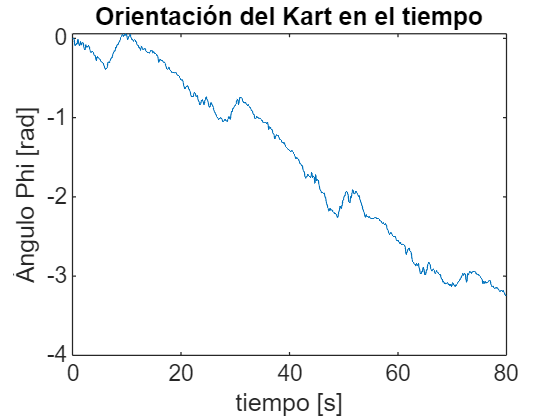



for i = 2:N

    %orientacion
    %phi(i) = phi(i-1) + sf_vel_angularY(i-1)*T;


    vel_angGl = Rot*[sf_vel_angularX(i-1);sf_vel_angularY(i-1);sf_vel_angularZ(i-1)];

    theta(i) = theta(i-1) + vel_angGl(1)*T;
    phi(i) = phi(i-1) + vel_angGl(2)*T;
    psi(i) = psi(i-1) + vel_angGl(3)*T;

    Rot = [1 0 0 ;
        0 cos(theta(i)) -sin(theta(i)) ; 
        0 sin(theta(i)) cos(theta(i))]*...
        [cos(phi(i)) 0  sin(phi(i)); 
        0 1 0 ;
        -sin(phi(i)) 0  cos(phi(i))]*...
        [cos(psi(i)) -sin(psi(i)) 0 ;
        sin(psi(i)) cos(psi(i)) 0;
        0 0 1 ];

    %Sistema Global
    accX_Gl(i) = sf_aceleracionX(i)*cos(phi(i)) + sf_aceleracionZ(i)*sin(phi(i));
    accZ_Gl(i) = sf_aceleracionZ(i)*cos(phi(i)) - sf_aceleracionX(i)*sin(phi(i));
    

    accRot = Rot*[sf_aceleracionX(i); sf_aceleracionY(i); sf_aceleracionZ(i)];
    accX_Gl(i) = accRot(1);
    accY_Gl(i) = accRot(2);
    accZ_Gl(i) = accRot(3);

    %integración de la aceleración
    velX(i) = velX(i-1) + accX_Gl(i) * T;
    velZ(i) = velZ(i-1) + accZ_Gl(i) * T;

    %integracion Velocidad
    posX(i) = posX(i-1) + velX(i) * T;
    posZ(i) = posZ(i-1) + velZ(i) * T;
end
plot(t,phi)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo Phi [rad]');

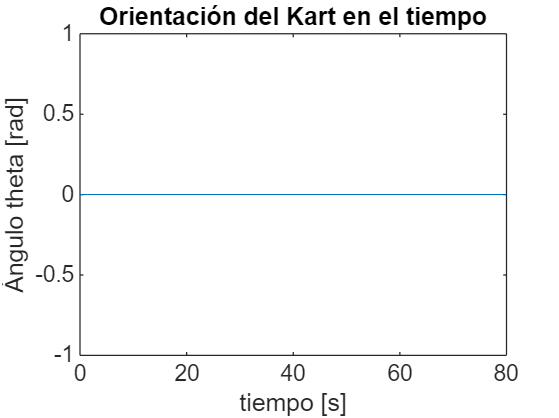


plot(t,theta)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo theta [rad]');

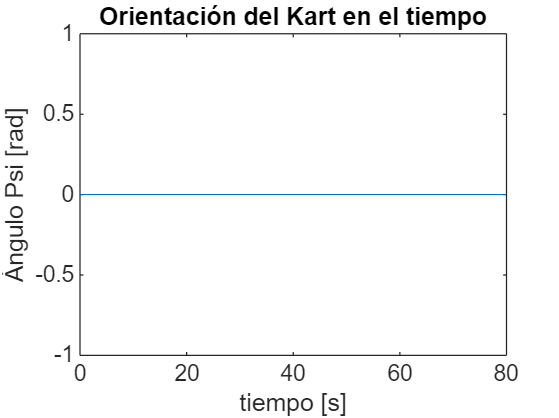


plot(t,psi)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo Psi [rad]');

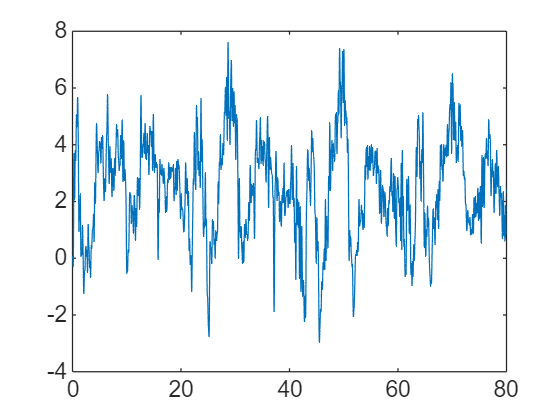


plot(t,sf_aceleracionX)

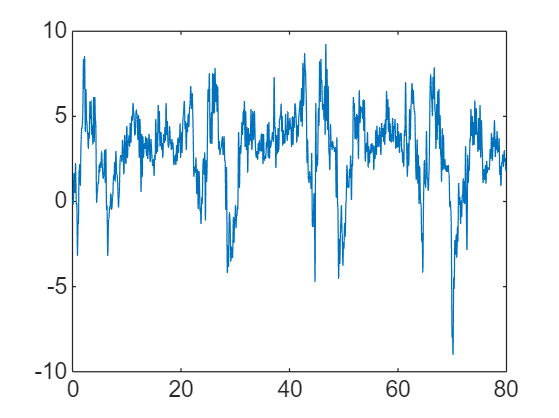

plot(t,sf_aceleracionZ)

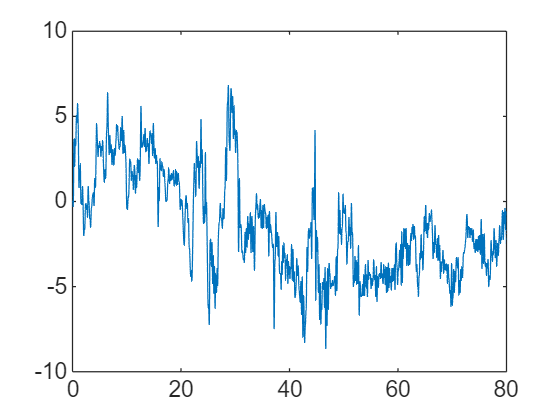


plot(t, accX_Gl)

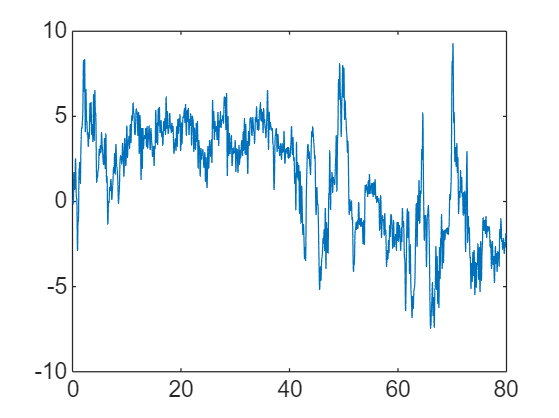

plot(t, accZ_Gl)

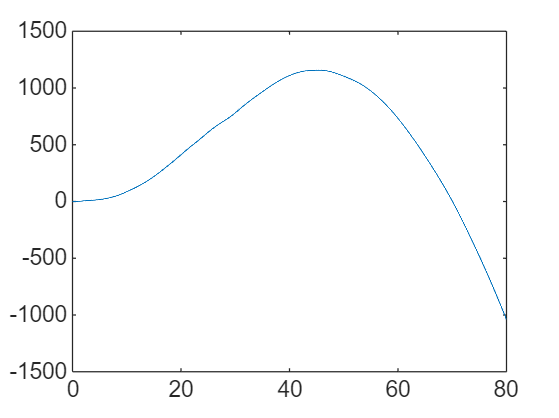


plot(t, posX)

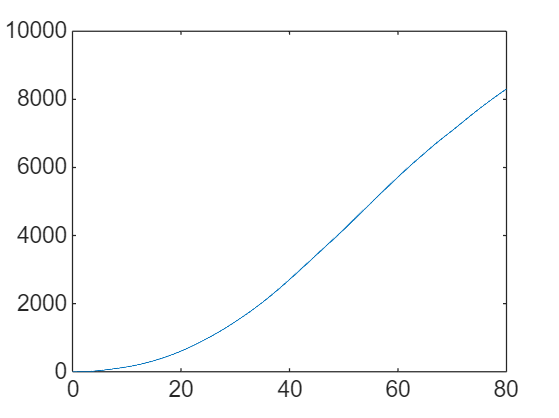

plot(t, posZ)

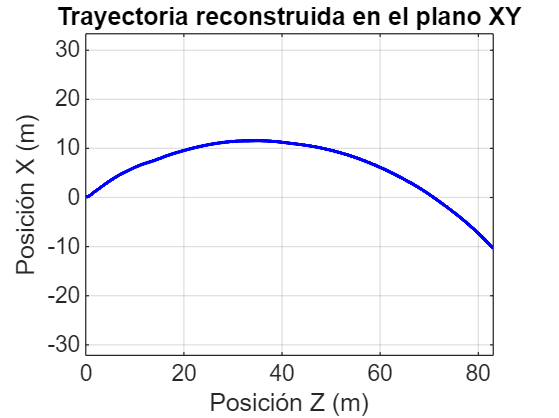

figure;
plot(posZ/100, posX/100, 'b', 'LineWidth', 1.5);
title('Trayectoria reconstruida en el plano XY');
xlabel('Posición Z (m)');
ylabel('Posición X (m)');
grid on;
axis equal;

También se realizó la gráfica de la trayectoria sin realizar la corrección de orientación a las velocidades angulares, esto es, tomanto el ángulo alrededor del eje y como la orientación del kart en cada momento y con la siguiente expresión pasar esa orientación a absoluto:


$$\phi \left(t\right)=\phi \left(t-1\right)+\hat{{\mathrm{vel}}_{\phi } } \left(t-1\right)*T$$


phi= zeros(1, N); %(rad)
theta = zeros(1, N); %(rad)
psi = zeros(1, N); %(rad)

velX = zeros(1, N); % (m/s)
velZ = zeros(1, N); % (m/s)
posX = zeros(1, N); % (m)
posZ = zeros(1, N); % (m)

accX_Gl = zeros(1, N);
accY_Gl = zeros(1, N);
accZ_Gl = zeros(1, N);

Rot = diag([1,1,1]);

velX(1) = accX_Gl(i) * T
velZ(1) = accZ_Gl(i) * T


for i = 2:N

    %orientacion
    phi(i) = phi(i-1) + sf_vel_angularY(i-1)*T;


    % vel_angGl = Rot*[sf_vel_angularX(i-1);sf_vel_angularY(i-1);sf_vel_angularZ(i-1)];
    % 
    % theta(i) = theta(i-1) + vel_angGl(1)*T;
    % phi(i) = phi(i-1) + vel_angGl(2)*T;
    % psi(i) = psi(i-1) + vel_angGl(3)*T;

    Rot = [1 0 0 ;
        0 cos(theta(i)) -sin(theta(i)) ; 
        0 sin(theta(i)) cos(theta(i))]*...
        [cos(phi(i)) 0  sin(phi(i)); 
        0 1 0 ;
        -sin(phi(i)) 0  cos(phi(i))]*...
        [cos(psi(i)) -sin(psi(i)) 0 ;
        sin(psi(i)) cos(psi(i)) 0;
        0 0 1 ];

    %Sistema Global
    accX_Gl(i) = sf_aceleracionX(i)*cos(phi(i)) + sf_aceleracionZ(i)*sin(phi(i));
    accZ_Gl(i) = sf_aceleracionZ(i)*cos(phi(i)) - sf_aceleracionX(i)*sin(phi(i));
    

    accRot = Rot*[sf_aceleracionX(i); sf_aceleracionY(i); sf_aceleracionZ(i)];
    accX_Gl(i) = accRot(1);
    accY_Gl(i) = accRot(2);
    accZ_Gl(i) = accRot(3);

    %integración de la aceleración
    velX(i) = velX(i-1) + accX_Gl(i) * T;
    velZ(i) = velZ(i-1) + accZ_Gl(i) * T;

    %integracion Velocidad
    posX(i) = posX(i-1) + velX(i) * T;
    posZ(i) = posZ(i-1) + velZ(i) * T;
end
plot(t,phi)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo Phi [rad]');

plot(t,theta)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo theta [rad]');

plot(t,psi)
title('Orientación del Kart en el tiempo');
xlabel('tiempo [s]');
ylabel('Ángulo Psi [rad]');

plot(t,sf_aceleracionX)
plot(t,sf_aceleracionZ)

plot(t, accX_Gl)
plot(t, accZ_Gl)

plot(t, posX)
plot(t, posZ)
figure;
plot(posZ/100, posX/100, 'b', 'LineWidth', 1.5);
title('Trayectoria reconstruida en el plano XY');
xlabel('Posición Z (m)');
ylabel('Posición X (m)');
grid on;
axis equal;

De los resultados de ambos enfoques se pueden destacar varias cosas. 

En el primer caso la trayectoria reconstruida es mas compleja, lo cual si bien es un buen aporte, se mantiene alejado del objetivo de reconstruccion de la trayectoria

En el segundo caso se puede observar que en la gráfica de la orientación del kart en el ángulo phi, se observa un patron repetitivo, correspondiente a las varias vueltas que se dieron a la pista en la toma de datos, sin embargo, tambien se observa un corrimiento de la medida, causado por un cambio de orientación del dispositivo de medida resultando en un error que se va acumulando en cada iteración.

En esta sección se construyeron las funciones de los filtros

Debido a que las señales captadas por el acelerómetro y el giroscopio presentaban un alto nivel de ruido, como se observó en las gráficas de los datos crudos, se decidió implementar un filtro pasabajos Butterworth, considerando que la mayor parte de la información se encuentra en las frecuencias más bajas. Para su implementación, fue necesario establecer dos parámetros: el orden del filtro, que se seleccionó de forma razonable ya que, aunque un orden más alto proporciona un filtrado más preciso, la mayoría de las señales a filtrar no requieren un tiempo de bajada excesivamente rápido, y la frecuencia de corte, que debido al diseño de la función no puede ingresarse directamente en Hz, sino que debe ser normalizada según la fórmula que la relaciona con la frecuencia de Nyquist.


$$$f_{normalizada} = \frac{f_{corte}}{f_{Nyquist}} = \frac{f_{corte}}{\frac{f_{muestra}}{2}$$$


function espectro_frec(var_filtrar, nombre, Fs)
    % Transformada de Fourier
    Y = fftshift(fft(var_filtrar)); % transformada y reacomodo para que aparezcan frecuencias positivas y negativas
    f = linspace(-Fs/2, Fs/2, length(Y)); % vector de frecuencias, por nyquist la grafica va a la mitad de la frecuencia de muestreo 
    
    mag_Y = abs(Y);  %extrae la magnitud de la tf
    
    figure();  %grafica
    plot(f, mag_Y/max(mag_Y)); % frecuencia vs transformada normalizada con el valor maximo de los datos
    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud normalizada');
    title(['Espectro de frecuencia de ', nombre]);
    grid on;
end

function var_filtrada = filtrar(Fs,fc, var_filtrar, titulo)
    N = 5; % orden filtro
    fcn = 2*fc/Fs; % Frecuencia de corte normalizada 
    [b, a] = butter(N, fcn, 'low'); % filtro butter, 'low' -> pasabajos

    var_filtrada = filtfilt(b, a, var_filtrar); % aplica filtro bidireccional para no inducir errores por cambios de fase

    % Graficar la señal filtrada y sin filtrar
    figure();
    plot(var_filtrar, 'b'); hold on;
    plot(var_filtrada, 'r');
    legend('Señal original', 'Señal filtrada');
    xlabel('t [seg]');
    ylabel('Amplitud');
    title(['LowPass Butterworth ', titulo]);
    grid on;
end

### Análisis

El desarrollo del ejercicio presentó diversas problemáticas, debidas principalmente la forma en que se recolectaron los datos. Al iniciar el registro, el sensor o el sistema DAQ registro como nulos los primeros registros, lo que ocasionó que los datos iniciales no reflejaran el estado estático del kart, que ya estaba en movimiento. Esto impidió contar con una zona de referencia estable que permitiera evaluar adecuadamente la influencia de variables como la gravedad, que podrían estar generando desfases adicionales en las mediciones.

Además, a pesar de haber corregido los ángulos y ajustar el sistema de referencia propio del dispositivo de medición. La ausencia de un modelo que integrara de manera precisa las influencias del entorno y la influencia de los otros ejes del dispositivo sobre una misma dirección en el sistema de referencias absoluto llevó a una acumulación de errores, que se hizo más visible al momento de integrar las velocidades y aceleraciones, lo que terminó afectando significativamente los resultados obtenidos.